%voltage transfer characteristics
v2_06=fcdiffampvtc(1:1801,:);
v2_08=fcdiffampvtc(1802:3601,:);
v2_10=fcdiffampvtc(3602:5402,:);
v2_12=fcdiffampvtc(5403:7203,:);
v2_14=fcdiffampvtc(7204:9004,:);
v2_16=fcdiffampvtc(9005:10805,:);

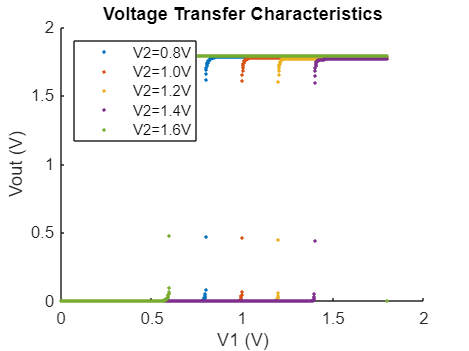

%plot
clf
figure
%plot(v2_06(:,2),v2_06(:,2),'.')
hold on
plot(v2_08(:,3),v2_08(:,2),'.')
plot(v2_10(:,3),v2_10(:,2),'.')
plot(v2_12(:,3),v2_12(:,2),'.')
plot(v2_14(:,3),v2_14(:,2),'.')
plot(v2_16(:,3),v2_06(:,2),'.')
title("Voltage Transfer Characteristics")
xlabel("V1 (V)")
ylabel("Vout (V)")
legend("V2=0.8V","V2=1.0V","V2=1.2V","V2=1.4V","V2=1.6V","location","northwest")

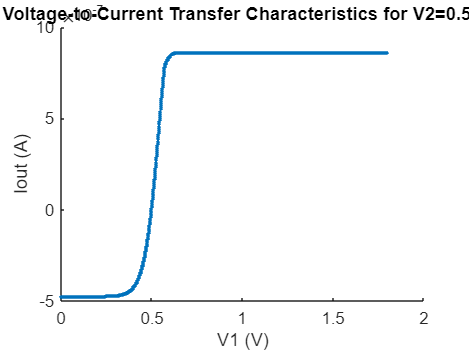

%voltage-to-current transfer characteristics
vtctc_v1 = fcdiffampvtctc(:,4);
vtctc_iout = fcdiffampvtctc(:,3);
clf
hold on
plot(vtctc_v1,vtctc_iout,'.')
title("Voltage-to-Current Transfer Characteristics for V2=0.5V")
xlabel("V1 (V)")
ylabel("Iout (A)")

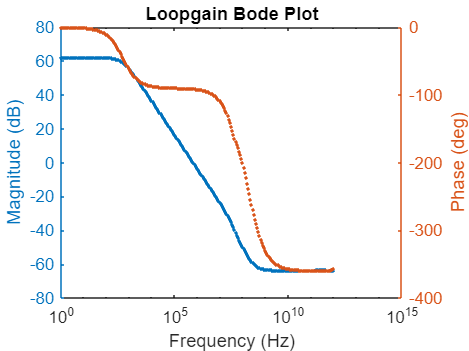

%loopgain
clf
loopgain_freq = fcdiffamploopgain(:,1);
loopgain_tmag = fcdiffamploopgain(:,2);
loopgain_tphase = fcdiffamploopgain(:,3);

yyaxis left
semilogx(loopgain_freq,loopgain_tmag,'.');
hold on
ylabel("Magnitude (dB)")
yyaxis right
semilogx(loopgain_freq,loopgain_tphase,'.');
ylabel("Phase (deg)")
title("Loopgain Bode Plot")
xlabel("Frequency (Hz)")

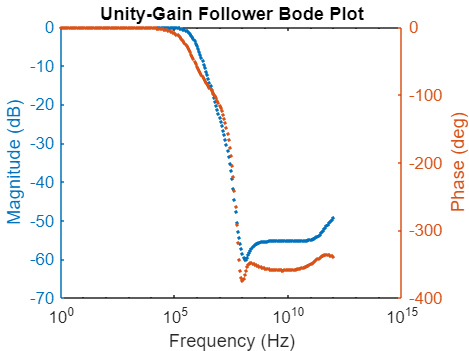

%unity gain follower response
clf
unitygain_freq = fcdiffampunitygain(:,1);
unitygain_tmag = fcdiffampunitygain(:,2);
unitygain_tphase = fcdiffampunitygain(:,3);

yyaxis left
semilogx(unitygain_freq,unitygain_tmag,'.');
hold on
ylabel("Magnitude (dB)")
yyaxis right
semilogx(unitygain_freq,unitygain_tphase,'.');
ylabel("Phase (deg)")
title("Unity-Gain Follower Bode Plot")
xlabel("Frequency (Hz)")